## Q2. Assignment modelling

#### a. Derive minimisation problems that you would solve to determine the UE and SO assignments

The links in the problem have costs:

$c_1(x_1) = a + x_1
$  and  $c_2(x_2) = 1 + bx_2$

Subject to:


$$x_1+x_2 = d$$



$$x_1,x_2 \geq 0$$


**User Equilibrium **occurs when the costs for either route become equal:


$$a+x_1 =1+{\textrm{bx}}_2$$



$$x_1 +x_2 =d$$


Solved such that:


$$x_1 =\frac{-a+\textrm{bd}+1}{b+1},x_2 =\frac{a+d-1}{b+1}$$


Whereas the **system optimal** solution considers when the total system travel time is minimised, and so the total travel time is the sum of the route costs multiplied by the respective flows:

Minimise:


$$\begin{array}{l}
{f\;=\;\textrm{ax}}_1 +x_1^2 +x_2 +{\textrm{bx}}_2^2 \\
x_1 +x_2 =d
\end{array}$$


This can be solved graphically (or using optimisation software), using f as an objective function, finding the minimum value of f that meets the demand constraint (plotting x_2 against x_1, f in green, constraint in red, for a=0.4, b=0.7, d= 1):

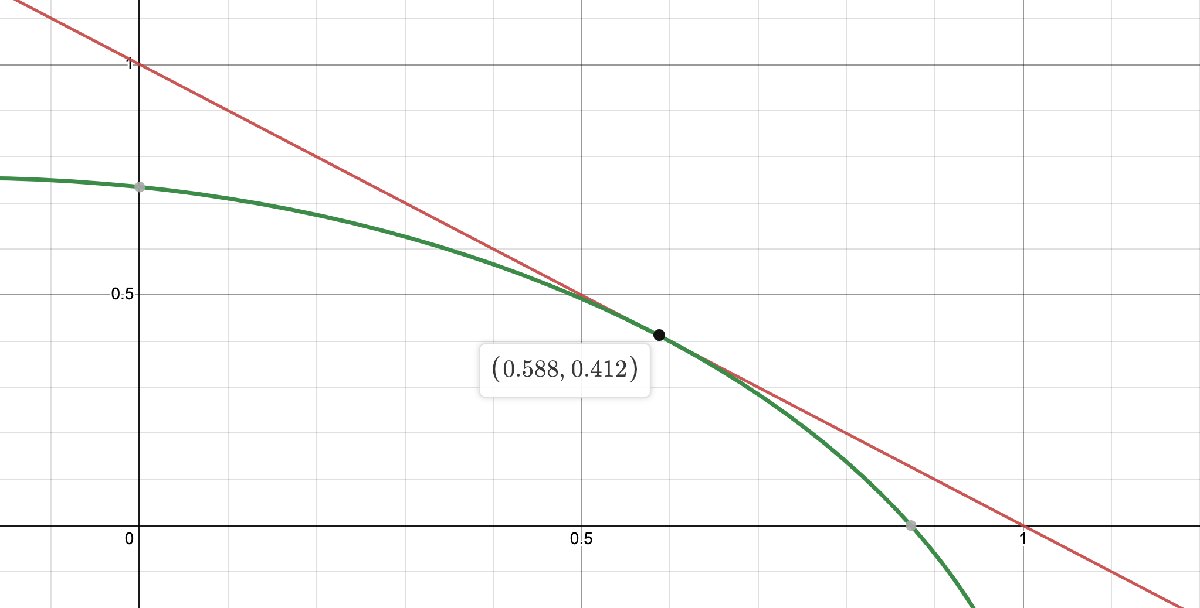

% define minimisation problem for User Equilibrium and System Optimal
a_var = 0.4;
b_var = 0.7;
d_var = 1;

H = [1, 0; 0, b_var]; % x^2 coefficients
f = [a_var; 1]; % x coefficients
Aeq = [1, 1];
beq = d_var;
options = optimoptions('quadprog', 'Display', 'off');

x_ue = UE_sol(H, f, Aeq, beq, options)

x_ue =     0.7647
    0.2353


x_so = SO_sol(H, f, Aeq, beq, options) % the quadratic coefficients *2

x_so =     0.5882
    0.4118


#### b. Price of Anarchy (PoA)

The PoA is the ratio of User Equilibrium Cost over the System Optimal Cost

In this case:


$$\mathrm{POA}=\frac{\sum_i x_i^{\mathrm{UE}} c_i }{\sum_i x_i^{\mathrm{SO}} c_i }=\;\frac{{x_1^{\mathrm{UE}} c}_1 \left(x_1^{\mathrm{UE}} \right)+x_2^{\mathrm{UE}} c_2 \left(x_2^{\mathrm{UE}} \right)}{{x_1^{\mathrm{SO}} c}_1 \left(x_2^{\mathrm{SO}} \right)+{x_1^{\mathrm{SO}} c}_2 \left(x_2^{\mathrm{SO}} \right)}$$


#### c. Varying demand for fixed a and b values

clf;
% Initialize matrices to store solutions
d_values = 0:0.01:1; % up to d=1 as thats the interesting bit
x_ue_vals = zeros(length(d_values), 2); 
x_so_vals = zeros(length(d_values), 2); 

cost_ue = zeros(length(d_values),1);
cost_so = zeros(length(d_values),1);

% Solve the UE problem for each demand value
for i = 1:length(d_values)
    d = d_values(i);

% Define matrix H, f, and equality constraint
    H = [1, 0; 0, b_var];
    f = [a_var; 1];
    Aeq = [1, 1];
    beq = d;
    
% Solve the quadratic programming problem using quadprog
    x_ue = quadprog(H, f, [], [], Aeq, beq,[0,0],[],[], options);
    x_so = quadprog(2*H, f, [],[], Aeq, beq,[0,0],[],[], options); 
    % H*2 in this case is the Beckmann Formulation
    
% Store the solution
    x_ue_vals(i, :) = x_ue';
    x_so_vals(i, :) = x_so';

    cost_ue(i) = x_ue_vals(i,1)*(a_var + x_ue_vals(i,1)) + x_ue_vals(i,2)*(1+b_var*x_ue_vals(i,2));
    cost_so(i) = x_so_vals(i,1)*(a_var + x_so_vals(i,1)) + x_so_vals(i,2)*(1+b_var*x_so_vals(i,2));
end

% POA 
poa = cost_ue./cost_so;
% find max POA
max_poa = max(poa)

max_poa = 1.0967

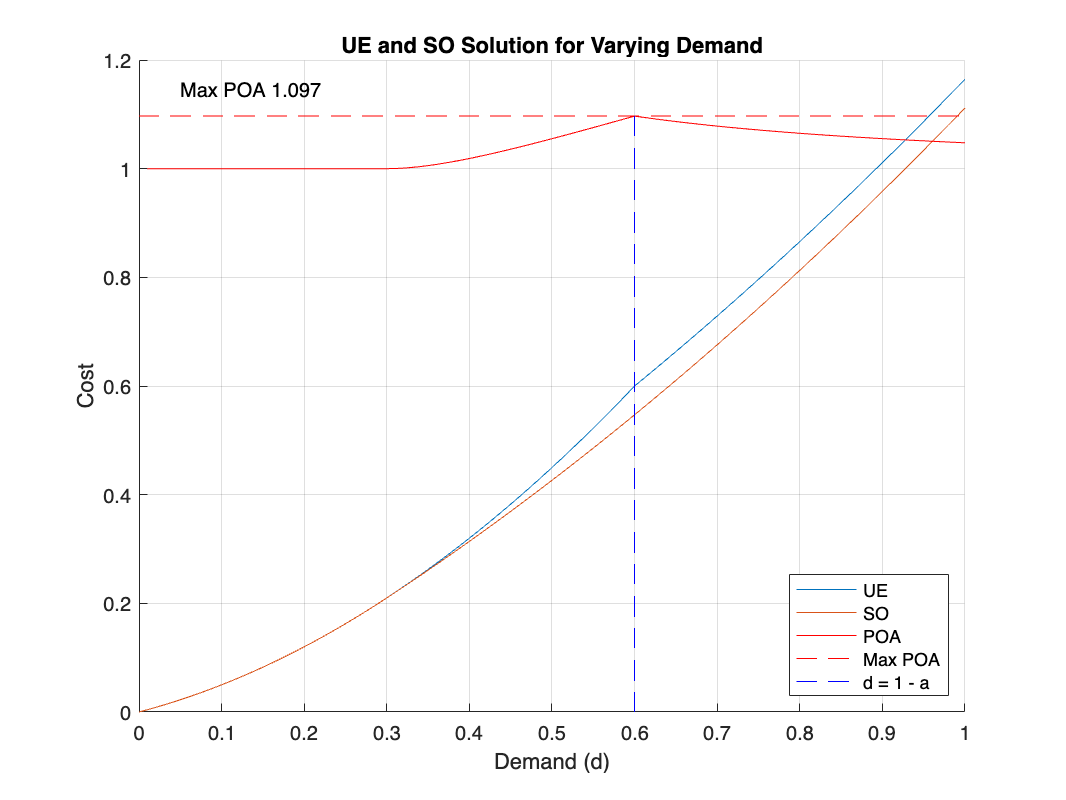

% Plot the results
figure;
hold on
plot(d_values, cost_ue, '-', 'DisplayName', 'UE');
plot(d_values, cost_so, '-', 'DisplayName', 'SO');
plot(d_values, poa, 'r-', 'DisplayName', 'POA');
% plot horizontal line for max poa
plot([0,max(d_values)],[max_poa, max_poa], 'r--', 'DisplayName','Max POA')
% plot where d=1-a
plot([1-a_var,1-a_var],[0,max_poa],'b--', 'DisplayName','d = 1 - a')

legend(Location="southeast");
xlabel('Demand (d)');
ylabel('Cost');
title('UE and SO Solution for Varying Demand');
text(0.05,max_poa+0.05,sprintf('Max POA %.3f', max_poa));
grid on;

The range of d chosen above has been decided by considering the original link cost functions, and the point of maximum POA. For 0 < a,b < 1 the maximum POA will always occur at d = 1 - a (for *a* within the bounds specified) and so d is not shown above 1 as the POA remains slowly tapering off from there onwards. As b tends to 1, and a tends to 1, the POA tends to 1.

#### d. Varying a and b and calculating the maximum POA for any value of d.

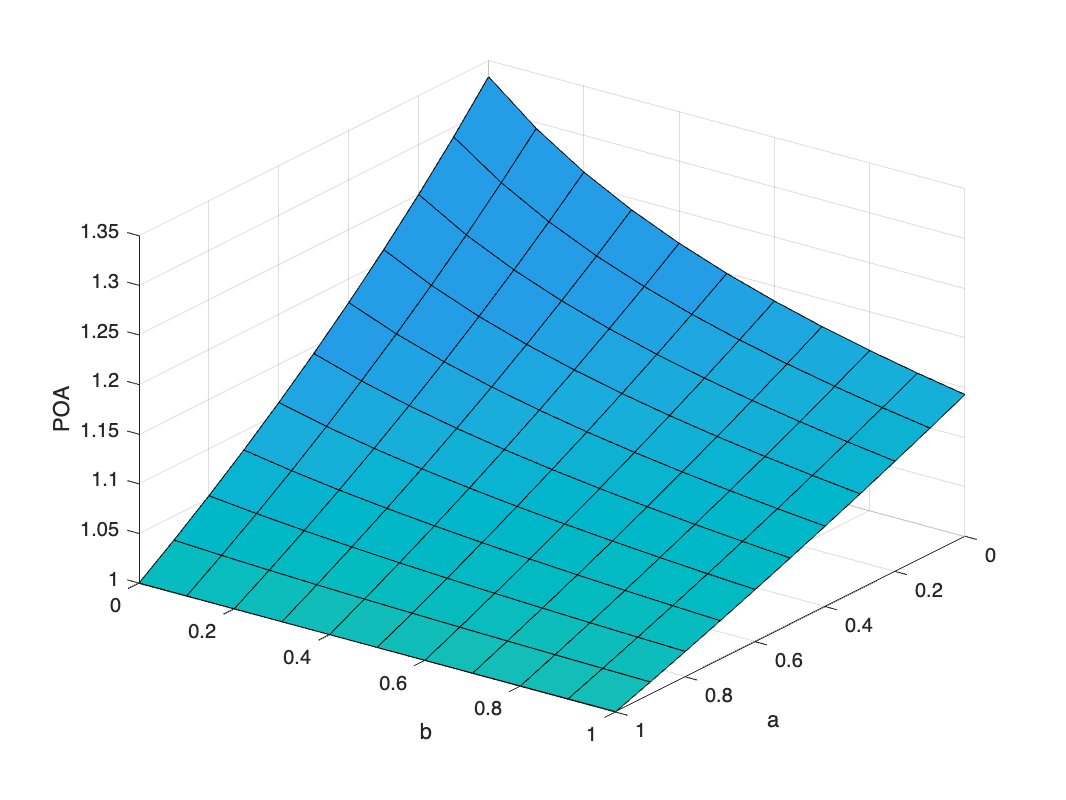

figure;
% plot the function
x = 0:0.1:1;
y = 0:0.1:1;
[X,Y] = meshgrid(x,y);
Z = zeros(size([X,Y]));
for i = 1:length(x)
    for ii = 1:length(y)
        Z(i,ii) = POA_ab([X(i,ii),Y(i,ii)]);
    end
end
surfl(X,Y,Z(:,1:length(x)))
xlabel('a')
ylabel('b')
zlabel('POA')

view([126.273 32.113]) % to make it clearer

By inspection it is clear that the maximum POA occurs when both a and b are 0, with the minimum occurring when a is 1. The maximum value of POA is 1.332. a and b both impact this value however only when a is not 1. When lim(a =1 and b=1) the costs for the routes are identical and so the UE and SO solutions will be the same. When lim(a=0 and b=0), the route costs will always remain as x_1 vs 1.

% find minimum
fun = @(x)(-POA_ab(x));
nvars = 2; % a and b
lb = [0,0];
ub = [1,1];
options = optimoptions('particleswarm','SwarmSize',10,MaxIterations=10);
[x, fval] = particleswarm(fun,nvars,lb,ub,options);

Optimization ended: number of iterations exceeded OPTIONS.MaxIterations.


% at maximum POA
a = x(1)

a = 0

b = x(2)

b = 0

Max_POA = -fval

Max_POA = 1.3332

Functions:

function sol = UE_sol(H, f, Aeq, beq, options)
    sol = quadprog(H, f, [], [], Aeq, beq, [0,0],[],[], options);
end

function sol = SO_sol(H,f, Aeq, beq, options)
    sol = quadprog(2*H, f, [], [], Aeq, beq, [0,0],[],[], options);
end

function max_poa = POA_ab(x)
    options = optimoptions('quadprog', 'Display', 'off');

    % unpackage a and b
    a_var = x(1);
    b_var = x(2);

    % Initialize matrices to store solutions
    d_values = 0:0.1:3; % 
    x_ue_vals = zeros(length(d_values), 2); 
    x_so_vals = zeros(length(d_values), 2); 
    
    cost_ue = zeros(length(d_values),1);
    cost_so = zeros(length(d_values),1);
    
    % Solve the UE problem for each demand value
    for i = 1:length(d_values)
        d = d_values(i);
    
    % Define matrix H, f, and equality constraint
        H = [1, 0; 0, b_var];
        f = [a_var; 1];
        Aeq = [1, 1];
        beq = d;
        
    % Solve the quadratic programming problem using quadprog
        x_ue = quadprog(H, f, [], [], Aeq, beq,[0,0],[],[], options);
        x_so = quadprog(2*H, f, [],[], Aeq, beq,[0,0],[],[], options); 
        % H*2 in this case is the Beckmann Formulation
        
    % Store the solution
        x_ue_vals(i, :) = x_ue';
        x_so_vals(i, :) = x_so';
    
        cost_ue(i) = x_ue_vals(i,1)*(a_var + x_ue_vals(i,1)) + x_ue_vals(i,2)*(1+b_var*x_ue_vals(i,2));
        cost_so(i) = x_so_vals(i,1)*(a_var + x_so_vals(i,1)) + x_so_vals(i,2)*(1+b_var*x_so_vals(i,2));
    end

    % POA 
    poa = cost_ue./cost_so;
    % find max POA
    max_poa = max(poa);
end
